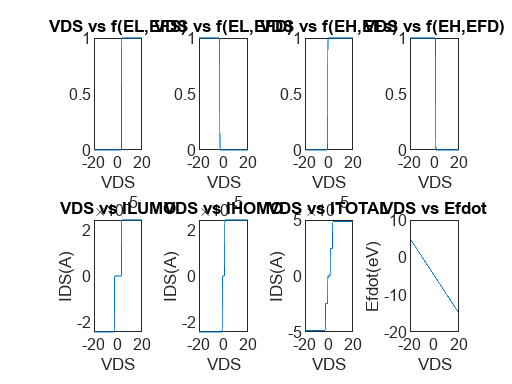

%MICRO-435 HW8 Question 8
%IDS-VDS curve for Quantum Dot

Elumo_init=-3.5; %LUMO=lowest unoccupied molecular orbit-not used
Ehomo_init=-5.5; %HOMO=highest occupied molecular orbit-not used
Esystem=-5; %Fermi energy of the source as reference
Coupling1=0.1; %Source coupling factor
Coupling2=0.1; %Drain coupling factor
Cs=0.5*1e-18; %attofarad=10^-18 farad, Source capacitor
Cd=0.5*1e-18; %drain capacitor
Cg=1e-18; %gate capacitor

q=1.6*1e-19; %coulomb
hbar=6.582*1e-16; %eV.s
kT=25.7*1e-3; %eV
kT_400=34.2*1e-3;

%define a VDS vector
VDS=-20:0.01:20;

%Efdot changes with changing VDS
Efdot=Esystem-0.5*VDS;

%Elumo and Ehomo changes with changing VDS since Efdot changes
Ehomo=Efdot-0.5;
Elumo=Efdot+1.5;

%Fermi Function for ELumo and EHomo
%EFdrain=EFsource-VDS
Fermi_EL_Efs=1./(exp((Elumo-Esystem)/kT)+1);
Fermi_EL_Efd=1./(exp((Elumo-(Esystem-VDS))/kT)+1);

Fermi_EH_Efs=1./(exp((Ehomo-Esystem)/kT)+1);
Fermi_EH_Efd=1./(exp((Ehomo-(Esystem-VDS))/kT)+1);


%Fermi Functions for T=400K
Fermi_EL_Efs_400=1./(exp((Elumo-Esystem)/kT_400)+1);
Fermi_EL_Efd_400=1./(exp((Elumo-(Esystem-VDS))/kT_400)+1);

Fermi_EH_Efs_400=1./(exp((Ehomo-Esystem)/kT_400)+1);
Fermi_EH_Efd_400=1./(exp((Ehomo-(Esystem-VDS))/kT_400)+1);

%current formula for LUMO and HOMO at T=300K
IDS_LUMO=(q*2*Coupling1*Coupling2)*(Fermi_EL_Efs-Fermi_EL_Efd)/(hbar*(Coupling1+Coupling2));
IDS_HOMO=(q*2*Coupling1*Coupling2)*(Fermi_EH_Efs-Fermi_EH_Efd)/(hbar*(Coupling1+Coupling2));
IDS=IDS_LUMO+IDS_HOMO;

%current formula for LUMO and HOMO at T=400K
IDS_LUMO_400=(q*2*Coupling1*Coupling2)*(Fermi_EL_Efs_400-Fermi_EL_Efd_400)/(hbar*(Coupling1+Coupling2));
IDS_HOMO_400=(q*2*Coupling1*Coupling2)*(Fermi_EH_Efs_400-Fermi_EH_Efd_400)/(hbar*(Coupling1+Coupling2));
IDS_400=IDS_LUMO_400+IDS_HOMO_400;

%Fermi Energy Plots
subplot(2,4,1);
plot(VDS,Fermi_EL_Efs);
xlabel('VDS');
title('VDS vs f(EL,EFS)');

subplot(2,4,2);
plot(VDS,Fermi_EL_Efd);
xlabel('VDS');
title('VDS vs f(EL,EFD)');

subplot(2,4,3);
plot(VDS,Fermi_EH_Efs);
xlabel('VDS');
title('VDS vs f(EH,EFs)');

subplot(2,4,4);
plot(VDS,Fermi_EH_Efd);
xlabel('VDS');
title('VDS vs f(EH,EFD)');

%IDS Curves
subplot(2,4,5)
plot(VDS,IDS_LUMO)
xlabel('VDS');
ylabel('IDS(A)')
title('VDS vs ILUMO');

subplot(2,4,6)
plot(VDS,IDS_HOMO)
xlabel('VDS');
ylabel('IDS(A)')
title('VDS vs IHOMO');

subplot(2,4,7)
plot(VDS,IDS)
xlabel('VDS');
ylabel('IDS(A)')
title('VDS vs ITOTAL');

%EFDOT
subplot(2,4,8)
plot(VDS,Efdot)
xlabel('VDS')
ylabel('Efdot(eV)')
title('VDS vs Efdot')

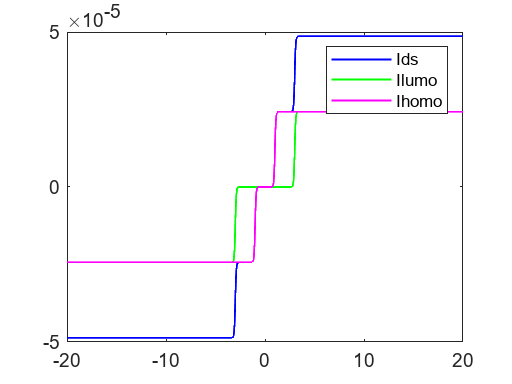


figure
plot(VDS,IDS,'b','LineWidth',1);
hold on
plot(VDS,IDS_LUMO,'g','LineWidth',1);
plot(VDS,IDS_HOMO,'m','LineWidth',1);

legend('Ids','Ilumo', 'Ihomo');

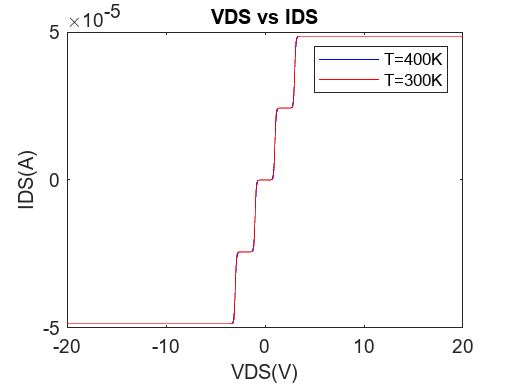


figure
plot(VDS,IDS_400,'b','LineWidth',0.5);
hold on

% plot(VDS,IDS_LUMO_400,'g','LineWidth',1);
% plot(VDS,IDS_HOMO_400,'m','LineWidth',1);

plot(VDS,IDS,'r','LineWidth',0.5);
legend('T=400K','T=300K');

xlabel('VDS(V)');
ylabel('IDS(A)');
title('VDS vs IDS');